# STEP 2: TRAJECTORY GENERATION

This step converts the discrete waypoints from Step 1 into a **smooth, time-parameterized trajectory**. 

We caculate $\textrm{position},\textrm{velocity},\textrm{and}\;\textrm{acceleration}$ at every simulation time step.

 A **quintic polynomial** is used for each segment because it allows the position, velocity, and acceleration to be specified at both the beginning and end of the segment.


$$\mathbf{p}_d(t) = [x_d(t)\;y_d(t)\;z_d(t)]^T$$



$$\mathbf{v}_d(t) = [v_{xd}(t)\;v_{yd}(t)\;v_{zd}(t)]^T$$



$$\mathbf{a}_d(t) = [a_{xd}(t)\;a_{yd}(t)\;a_{zd}(t)]^T$$


clc;
clear;
close all;

load('drone_toy_model.mat');
N = size(waypoints,1);

dt = 0.01;

t = (waypointTime(1):dt:waypointTime(end))';

numSamples = length(t);


The trajectory is evaluated at a fixed time interval of dt=0.01 s. This creates a sequence of time samples from the first waypoint time to the final waypoint time.


$$\Delta t = 0.01\ \mathrm{s}$$


$t_k = t_0 + k\Delta t
$ where k = 0,1,2..

% Desired position
pd = zeros(numSamples,3);

% Desired velocity
vd = zeros(numSamples,3);

% Desired acceleration
ad = zeros(numSamples,3);


### Quintic Polynomial Representation

A fifth-order polynomial has six coefficients. This is important because six boundary conditions are imposed: position, velocity, and acceleration at both ends of the segment.


$$q(\tau)
=
c_0+c_1\tau+c_2\tau^2+c_3\tau^3+c_4\tau^4+c_5\tau^5$$


The corresponding velocity is obtained by differentiating position:


$$\dot q(\tau)
=
c_1+2c_2\tau+3c_3\tau^2+4c_4\tau^3+5c_5\tau^4$$


The acceleration is obtained by differentiating velocity:


$$\ddot q(\tau)
=
2c_2+6c_3\tau+12c_4\tau^2+20c_5\tau^3$$


%% 3. Generate Trajectory Segment by Segment

for i = 1:N-1

    % -----------------------------------------------------
    % Segment start and end time
    % -----------------------------------------------------

    t0 = waypointTime(i);
    tf = waypointTime(i+1);

    % Segment duration
    T = tf - t0;


    % -----------------------------------------------------
    % Select time samples belonging to this segment
    % -----------------------------------------------------

    if i < N-1
        idx = t >= t0 & t < tf;
    else
        idx = t >= t0 & t <= tf;
    end

    % Local time within the current segment
    tau = t(idx) - t0;


    % -----------------------------------------------------
    % Quintic polynomial coefficient matrix
    % -----------------------------------------------------

    A = [
        1  0   0    0      0       0;
        1  T   T^2  T^3    T^4     T^5;
        0  1   0    0      0       0;
        0  1   2*T  3*T^2  4*T^3   5*T^4;
        0  0   2    0      0       0;
        0  0   2    6*T    12*T^2  20*T^3
    ];


    % -----------------------------------------------------
    % Position basis
    % -----------------------------------------------------

    P = [
        ones(size(tau)) ...
        tau ...
        tau.^2 ...
        tau.^3 ...
        tau.^4 ...
        tau.^5
    ];


    % -----------------------------------------------------
    % Velocity basis
    % -----------------------------------------------------

    V = [
        zeros(size(tau)) ...
        ones(size(tau)) ...
        2*tau ...
        3*tau.^2 ...
        4*tau.^3 ...
        5*tau.^4
    ];


    % -----------------------------------------------------
    % Acceleration basis
    % -----------------------------------------------------

    Acc = [
        zeros(size(tau)) ...
        zeros(size(tau)) ...
        2*ones(size(tau)) ...
        6*tau ...
        12*tau.^2 ...
        20*tau.^3
    ];


    % -----------------------------------------------------
    % Generate x, y and z trajectories
    % -----------------------------------------------------

    for axis = 1:3

        % Initial and final coordinate
        q0 = waypoints(i,axis);
        qf = waypoints(i+1,axis);

        b = [
            q0;
            qf;
            0;
            0;
            0;
            0
        ];


        % Solve for quintic polynomial coefficients
        coefficients = A\b;


        % Generate desired position
        pd(idx,axis) = P * coefficients;

        % Generate desired velocity
        vd(idx,axis) = V * coefficients;

        % Generate desired acceleration
        ad(idx,axis) = Acc * coefficients;

    end

end

velocity and acceleration to zero at both endpoints

*The six boundary conditions are:*


$$q(0)=q_0$$



$$q(T)=q_f$$



$$\dot q(0)=0,\qquad \dot q(T)=0$$



$$\ddot q(0)=0,\qquad \ddot q(T)=0$$



$$A\mathbf{c}=\mathbf{b}$$



$$\mathbf{c}=[c_0\;c_1\;c_2\;c_3\;c_4\;c_5]^T$$



$$A =
\left[
\begin{array}{cccccc}
1&0&0&0&0&0\\
1&T&T^2&T^3&T^4&T^5\\
0&1&0&0&0&0\\
0&1&2T&3T^2&4T^3&5T^4\\
0&0&2&0&0&0\\
0&0&2&6T&12T^2&20T^3
\end{array}
\right]$$


### Position


$$P(\tau)=[1\;\tau\;\tau^2\;\tau^3\;\tau^4\;\tau^5]$$



$$q(\tau)=P(\tau)\mathbf{c}$$


### Velocity


$$V(\tau)=[0\;1\;2\tau\;3\tau^2\;4\tau^3\;5\tau^4]$$



$$\dot q(\tau)=V(\tau)\mathbf{c}$$


### Acceleration


$$Acc(\tau)=[0\;0\;2\;6\tau\;12\tau^2\;20\tau^3]
$$



$$\ddot q(\tau)=Acc(\tau)\mathbf{c}$$



%% 4. Verify Generated Trajectory

if max(abs(pd(:))) < 1e-10
    error('Trajectory generation failed: pd contains only zeros.');
end

if max(abs(vd(:))) < 1e-10
    error('Trajectory generation failed: vd contains only zeros.');
end

if max(abs(ad(:))) < 1e-10
    error('Trajectory generation failed: ad contains only zeros.');
end


fprintf('Trajectory generation successful.\n');

Trajectory generation successful.


fprintf('Maximum position = %.4f m\n', ...
    max(abs(pd(:))));

Maximum position = 4.0000 m



fprintf('Maximum velocity = %.4f m/s\n', ...
    max(abs(vd(:))));

Maximum velocity = 1.8750 m/s



fprintf('Maximum acceleration = %.4f m/s^2\n', ...
    max(abs(ad(:))));

Maximum acceleration = 2.8867 m/s^2


Desired Position,Velocity and Acceleration plotted against time

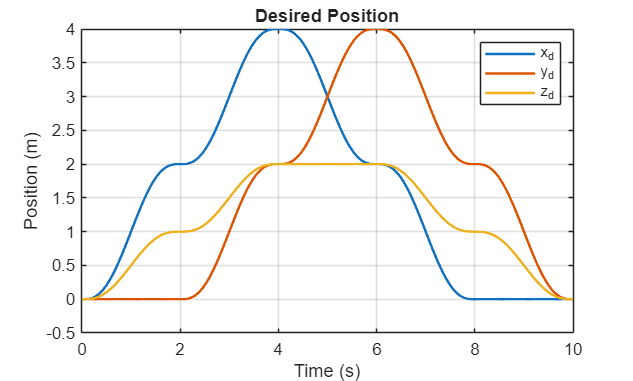

%% 5. Plot Desired Position

figure;

plot(t,pd(:,1),'LineWidth',1.5);
hold on;

plot(t,pd(:,2),'LineWidth',1.5);
plot(t,pd(:,3),'LineWidth',1.5);

xlabel('Time (s)');
ylabel('Position (m)');

title('Desired Position');

legend('x_d','y_d','z_d');

grid on;

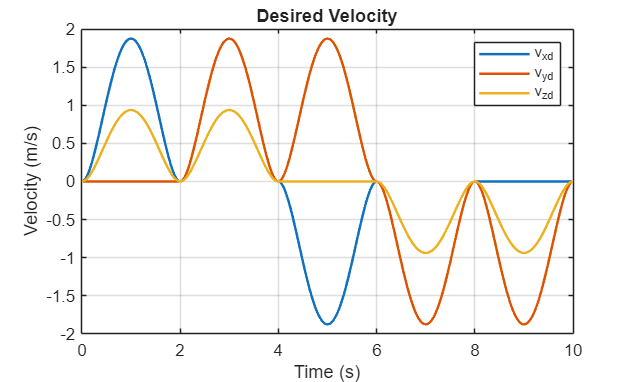



%% 6. Plot Desired Velocity

figure;

plot(t,vd(:,1),'LineWidth',1.5);
hold on;

plot(t,vd(:,2),'LineWidth',1.5);
plot(t,vd(:,3),'LineWidth',1.5);

xlabel('Time (s)');
ylabel('Velocity (m/s)');

title('Desired Velocity');

legend('v_{xd}','v_{yd}','v_{zd}');

grid on;

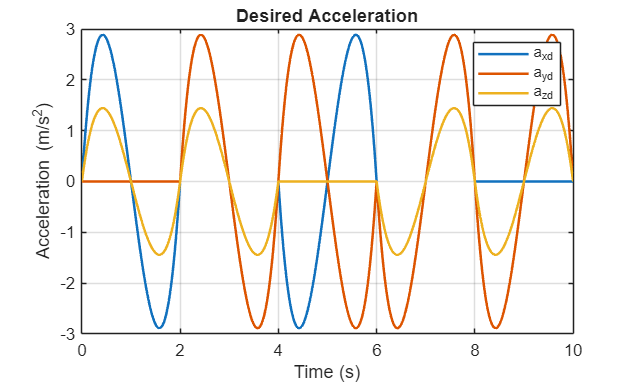



%% 7. Plot Desired Acceleration

figure;

plot(t,ad(:,1),'LineWidth',1.5);
hold on;

plot(t,ad(:,2),'LineWidth',1.5);
plot(t,ad(:,3),'LineWidth',1.5);

xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

title('Desired Acceleration');

legend('a_{xd}','a_{yd}','a_{zd}');

grid on;

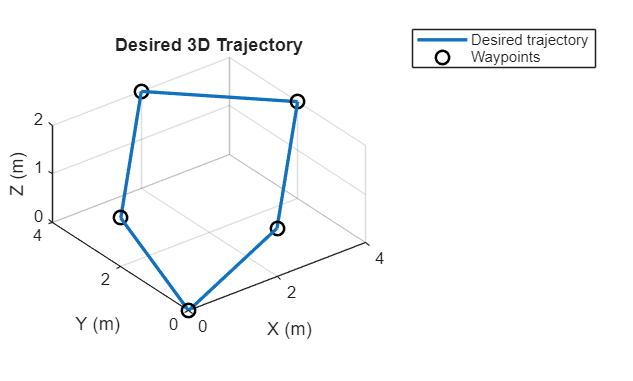



%% 8. Plot Desired 3D Trajectory

figure;

plot3( ...
    pd(:,1), ...
    pd(:,2), ...
    pd(:,3), ...
    'LineWidth',2);

hold on;

plot3( ...
    waypoints(:,1), ...
    waypoints(:,2), ...
    waypoints(:,3), ...
    'ko', ...
    'MarkerSize',8, ...
    'LineWidth',1.5);

grid on;
axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('Desired 3D Trajectory');

legend( ...
    'Desired trajectory', ...
    'Waypoints');



%% 9. Save Step 2 Results

save( ...
    'drone_toy_model.mat', ...
    'waypoints', ...
    'waypointTime', ...
    't', ...
    'dt', ...
    'pd', ...
    'vd', ...
    'ad');

fprintf('\nStep 2 results saved to drone_toy_model.mat\n');


Step 2 results saved to drone_toy_model.mat


pd

pd =          0         0         0
    0.0000         0    0.0000
    0.0000         0    0.0000
    0.0001         0    0.0000
    0.0002         0    0.0001
    0.0003         0    0.0002
    0.0005         0    0.0003
    0.0008         0    0.0004
    0.0012         0    0.0006
    0.0017         0    0.0009
    0.0023         0    0.0012
    0.0031         0    0.0015
    0.0039         0    0.0020
    0.0050         0    0.0025
    0.0062         0    0.0031
